# Plot Electricity Usage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

usage = table2array(readtable("../data/electricityData.xlsx", "Sheet", "usage", "NumHeaderLines", 0));
dates = table2array(readtable("../data/electricityData.xlsx", "Sheet", "dates", "NumHeaderLines", 0));
sectors = table2array(readtable("../data/electricityData.xlsx", "Sheet", "sectors", "ReadVariableNames", false));
whos

  Name           Size            Bytes  Class       Attributes

  dates        315x1              2542  datetime              
  sectors        1x4               488  cell                  
  usage        315x4             10080  double                



usagesmooth = movmean(usage, 24);
totalSm = usagesmooth(:, end);
sectorUsageSm = usagesmooth(:, 1:3);

## Task 1

yyaxis left
plot(dates, sectorUsageSm)
grid minor
yyaxis right
plot(dates, totalSm)

Do not edit. This code adds a legend.

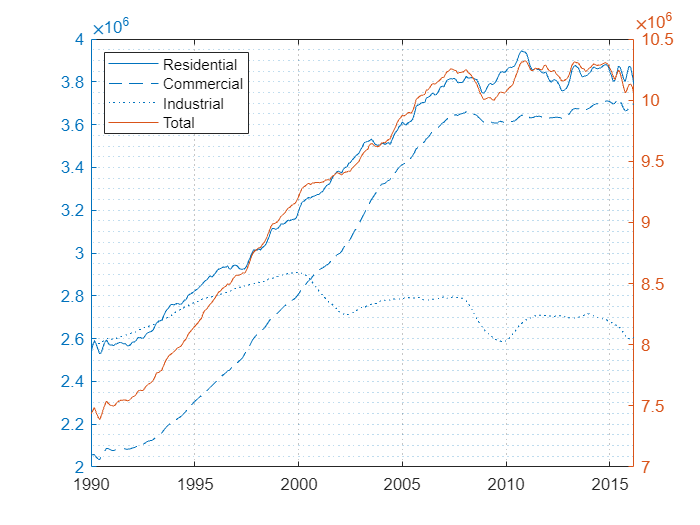

legend(sectors, "Location", "northwest")